# Identifying lane markings

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code imports an image of a road and displays it.

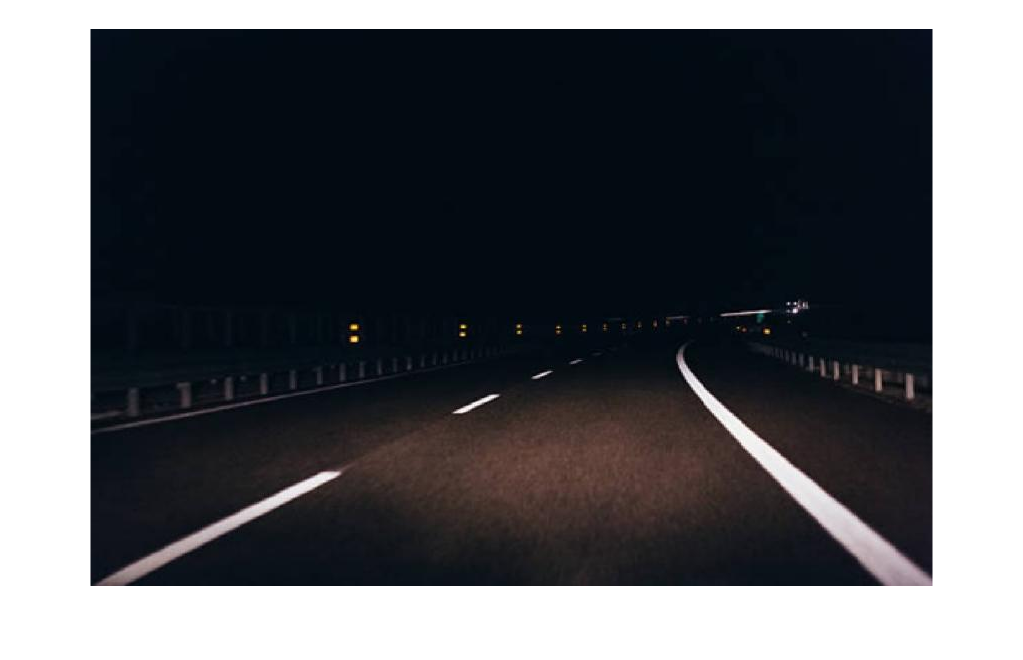

lanes = imread("./images/lanes.jpg");
imshow(lanes)

This code binarizes the image and then removes regions with fewer than 200 pixels.

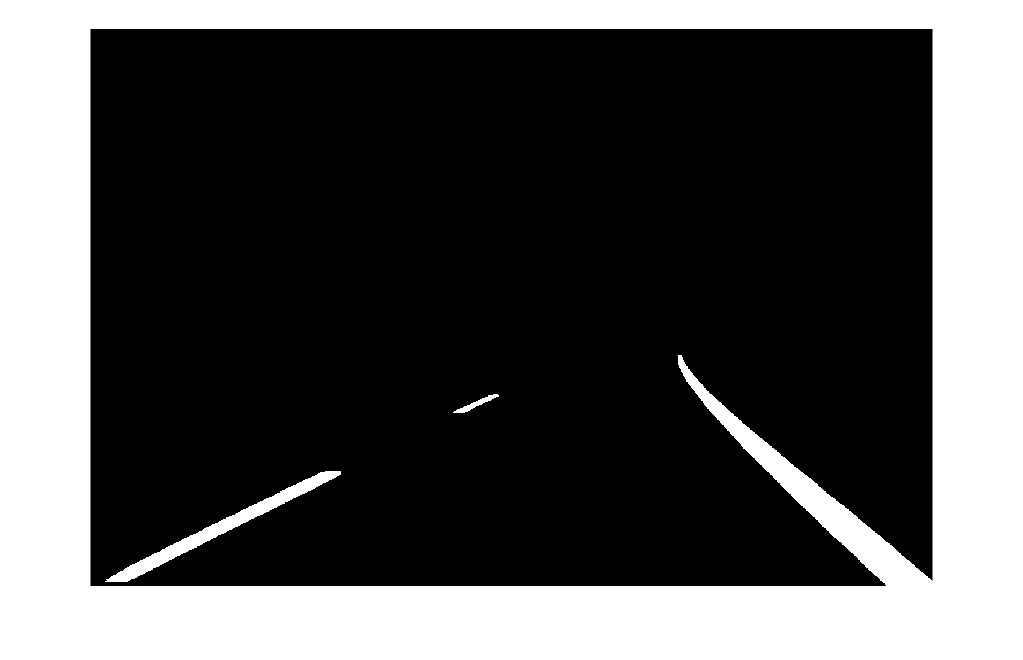

lanesGray = im2gray(lanes);
lanesBW = imbinarize(lanesGray);
lanesBW = bwareaopen(lanesBW, 200);
imshow(lanesBW)

## Task 1

To avoid identifying many lines per lane marking, you can reduce their thickness. This process is known as skeletonization and can be performed with the `bwmorph` function.

`BW2` `=` `bwmorph``(``BW``,``operation``,``n``)``;`

The second input determines which morphological operation will be applied to the binary image `BW`. The third input, `n`, determines how many times that operation will be applied. Setting `n` to `Inf` will cause the operation to be repeated until the image no longer changes.

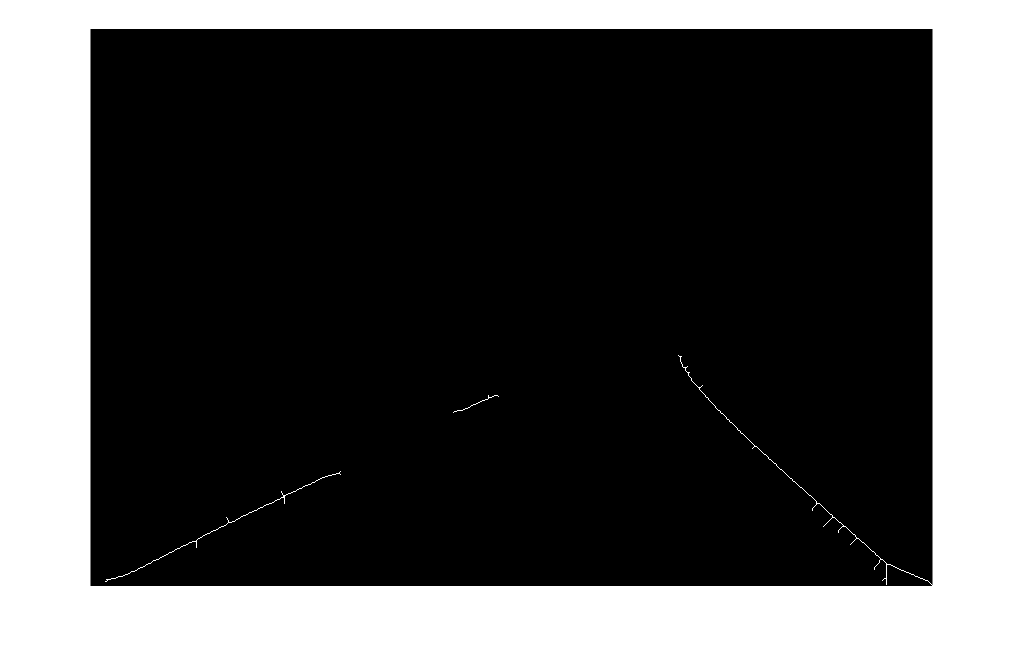

lanesSkel = bwmorph(lanesBW, "skel", Inf);
imshow(lanesSkel)

## Task 2

You can use the `hough` function to compute the Hough transform of a binary image. This is the first of three functions used to identify straight lines.

`[``H``,``theta``,``rho``]` `=` `hough``(``BW``)``;`

[H, T, R] = hough(lanesSkel);

## Task 3

It takes a few lines of code to make a nice plot of the Hough transform. A function that visualizes the Hough transform matrix is included at the bottom of the script.

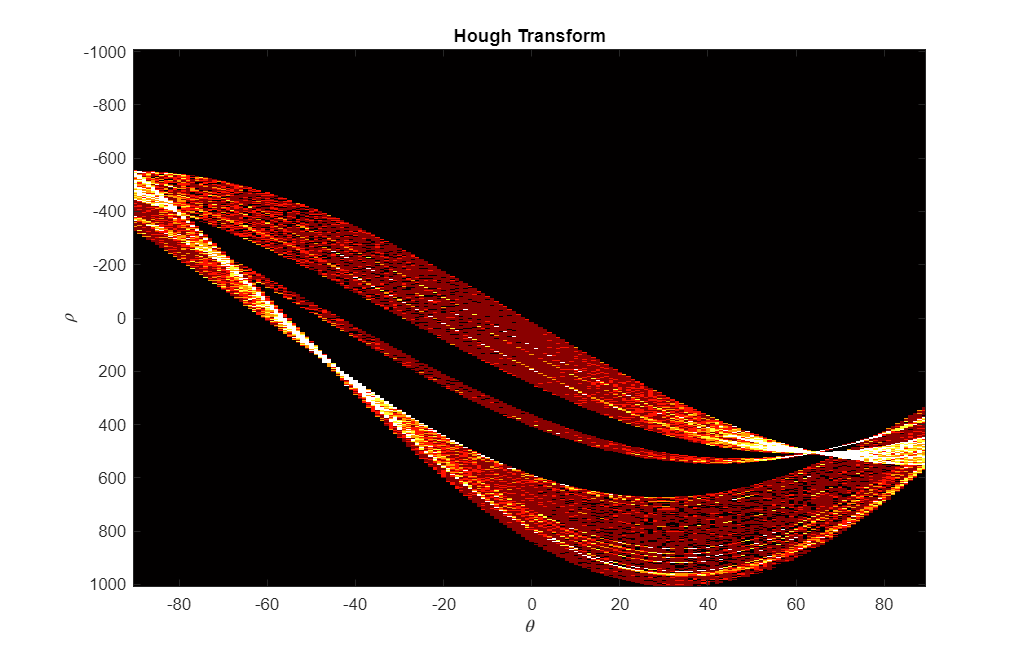

houghMatViz(H, T, R)

## Task 4

How many peaks do you see in the Hough transform? Peaks occur in the hough transform where the sinusoids created by individual pixels cross. You can identify the peaks using `houghpeaks`.

`peaks` `=` `houghpeaks``(``H``,``numpeaks``)`

The second parameter `numpeaks` determines the maximum number of peaks identified.

peaks = houghpeaks(H, 10)

peaks =         1514         155
        1145          43
        1185          46


## Task 5

How many peaks did `houghpeaks` find? You'll notice that it wasn't 10. That's because, with the default settings, `houghpeaks` only finds prominent peaks. As you can see in the plot of the Hough transform, there are only two prominent peaks.

Now that you have identified the peaks, you can find lines in the image.

`lines` `=` `houghlines``(``BW``,``theta``,``rho``,``peaks``)`

lines = houghlines(lanesSkel, T, R, peaks)

lines = 1×3 struct array with fields:
    point1
    point2
    theta
    rho


## Task 6

The output of `houghlines`, `lines`, is a structure array that contains fields for the end-points of the identified line segments: `point1` and `point2`. Plotting these lines requires a little parsing. A second local function, `plotHoughLines`, is included at the bottom of the script to parse and plot the lines.

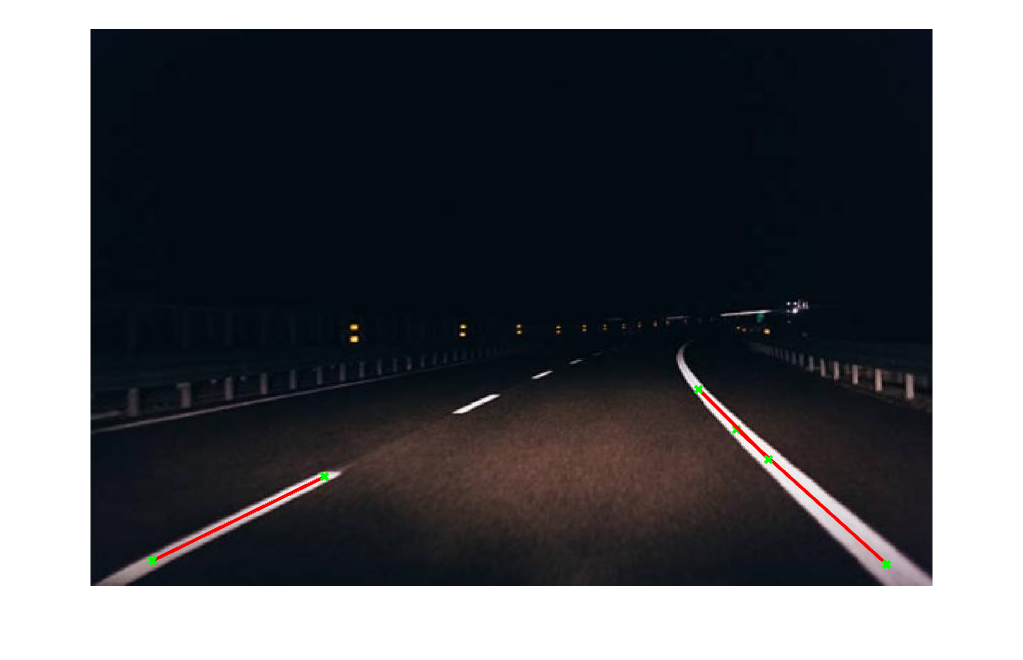

plotHoughLines(lanes, lines)

function houghMatViz(H, T, R)
    % Convert the hough matrix to a grayscale image
    Hgray = mat2gray(H);
    % Enhance its brightness
    Hgray = imadjust(Hgray);
    % Display the hough transform
    imagesc(Hgray, "XData", T, "YData", R) 
    % Assign a colormap for the image
    colormap(hot)
    title("Hough Transform")
    % Add x-y labels
    xlabel("\theta")
    ylabel("\rho")
end

function plotHoughLines(image, lines)
    % Show the image
    imshow(image)
    % Plot the hough transform lines
    hold on    
    numLines = length(lines);
    for k = 1:numLines
        xy = [lines(k).point1; lines(k).point2];
        plot(xy(:, 1), xy(:, 2), "LineWidth", 2, "Color", "red",...
            "Marker", "x", "MarkerEdgeColor", "g")
    end
    hold off
end